Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# SASE free-electron laser (Section 10.4)

Volker Ziemann, 211114, CC-BY-SA-4.0

**Important:** requires the elliptic package from [https://github.com/moiseevigor/elliptic](https://github.com/moiseevigor/elliptic) located in a subdirectory below the present one (for the fast evaluation of elliptic functions).

In this simulation we numerically integrate Equation 10.32, which describes the evolution of the amplitude and phase of the electro-magnetic wave (the laser field) and an ensemble of electrons that move in the ponderomotive field of the laser. 

First we define the initial complex field `a` of the laser and the scaled current `jcurr`, which represents the peak current of the electron distribution. Moreover, we define the initial distribution of electrons in the ponderomotive field and the number `N` of electrons used in the simulation. From Equation 10.32 we see that the magnnitude of `a`, which is `a0` describes the oscillation frequency $\Omega_s$ in the ponderomotive field.

clear all; close all
addpath ./elliptic                 % needed for elliptic12
a0=1e-8; phi=0; a=a0*exp(i*phi);   % initial amplitude and phase of laser
jcurr=200;                         % scaled current from Equation 10.32
x0=[pi/2,0]; dx=[2*pi,0.3];        % center and spread of distribution
N=1000;                            % number of particles
Omegas=sqrt(a0);                   % synchrotron frequency

Now we can plot the initial electron distribution as a cloud of green dots . We see that it is evenly distributed in phase and has a small vertical extent in the variable $\nu$ which corresponds to the difference of electron energy with respect to the resonance energy of the FEL.

axis_scale=[-pi/2,3*pi/2,-17,17];
ypos=0.95*axis_scale(3)+0.05*axis_scale(4); % where to place text
zeta=-pi/2:0.01:3*pi/2; separatrix=2*Omegas*cos(0.5*(zeta-pi/2+phi));
hold off; plot(zeta,separatrix,'k',zeta,-separatrix,'k')
axis(axis_scale); xlabel('\zeta'); ylabel('\nu')
set(gca,'xtick',[-pi/2,0,pi/2,pi,3*pi/2],'fontsize',14, ...
  'xticklabels',{'-\pi/2','0','\pi/2','\pi','3\pi/2'})
hold on;
x1(:,1)=x0(1)+(rand(N,1)-0.5)*dx(1); % initial distribution
x1(:,2)=x0(2)+(rand(N,1)-0.5)*dx(2); 
plot(x1(:,1),x1(:,2),'g.')
title('Initial Distribution')
pause(0.01)

After subdividing the time for the transit through the FEL into `nstep=100` time steps, we are ready to start iterating

nstep=100; dt=1/nstep; tau=(1:nstep)/nstep; % steps along the undulator
tic; data=zeros(nstep,4);  % storage for plot data
for m=1:nstep
  hold off; % draw new image

As a first step we calculate $\Omega_s$ and phase $\phi$ from the amplitude of the field, which enables us to plot the separatrix, whose height is thus related to the field amplitude and phase.

  Omegas=sqrt(abs(a)); phi=phase(a);  % needed for electron dynamics
  separatrix=2*Omegas*cos(0.5*(zeta-pi/2+phi));
  plot(zeta,separatrix,'k',zeta,-separatrix,'k'); 
  set(gca,'xtick',[-pi/2,0,pi/2,pi,3*pi/2],'fontsize',14, ...
    'xticklabels',{'-\pi/2','0','\pi/2','\pi','3\pi/2'}) 
  axis(axis_scale); xlabel('\zeta'); ylabel('\nu')

Now we update the positions of all electrons in their phase space, which is governed by the pendulum equation and uses pendulumtracker2_phase(), which is a slightly modified version of the equivalent function from Chapter 5, but this one is centered aroudn $\pi/2$ insetead of zero. See the code below. Once all electrons coordinates are updated, we plot them as  red dots superimposed to the separatrix. Note that all electrons are independent and we use parfor as a simple ay to utilize all processor cores.

  hold on
  parfor k=1:N   % update electron phase space, use "for" or "parfor"
    x1(k,:)=pendulumtracker2_phase(x1(k,:),Omegas,phi,dt);
  end
  plot(x1(:,1),x1(:,2),'r.'); 

Now we calculate the bunching factor, which appears on the right-hand side of the equation for $a$ in Equation 10.32 and numerically integrate that equation in order to update amplitude and phase of the laser field.

  bf=sum(exp(-i*x1(:,1)))/size(x1,1);  % bunching factor <exp(-i*zeta)>
  a=a-jcurr*bf*dt;                     % update laser field, Eq. 10.32

Now all dynamical variables are updated for this time step and we annotate the plot and save the interesting quantities to the array `data`. The short pause at the end allows MATLAB to update the plot so we can watch the evolution in real time. Note how the seapatrix grows as the field amplitude grows and, at the same time, the phase of the separatrix shifts towards is the electrons transfer their kinetic energy to the laser field.

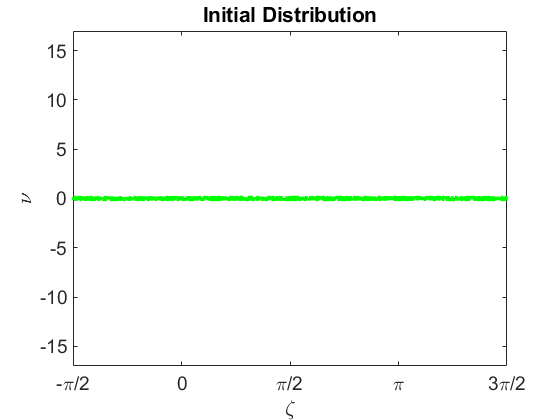

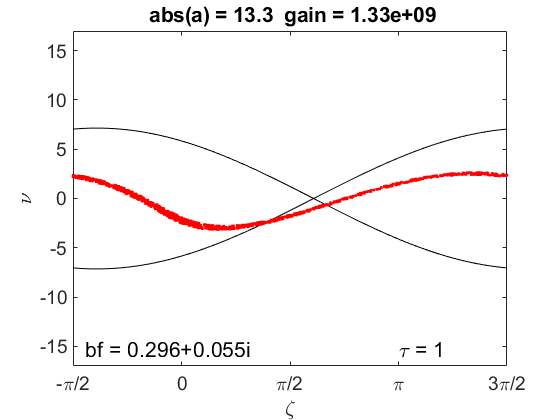

  text(-1.4,ypos,['bf = ',num2str(bf,'%6.3f'),' '],'fontsize',16) 
  text(pi,ypos,['\tau = ',num2str(tau(m),4),' '],'fontsize',16) 
  data(m,1)=abs(a);
  data(m,2)=phase(a)*180/pi;
  data(m,3)=abs(bf);
  data(m,4)=(abs(a)-a0)/a0;
  title([' abs(a) = ',num2str(abs(a),3),'  gain = ' num2str(data(m,4),3)])
  pause(0.01)
end

Once the simulation is complete, we calculate the theoretical exponential gain from Equation 10.33 and also from a fit to the final part of the numerically determined growth of` a`. The upper plot shows latter growth and also shows the theoretical and experimentally determined growth rate in the title.

toc; growth_theo=0.5*sqrt(3)*(jcurr/2)^(1/3);

Elapsed time is 14.680380 seconds.


mm=0.3*nstep:nstep; p=polyfit(tau(mm)',log(data(mm,1)),1);
growth_rate=p(1);
figure;   % second figure with evaolution along the undulator tau=s/L
subplot(4,1,1); plot(tau,data(:,1),'k'); ylabel('abs(a)');
title(['Growth rate [theo/exp] = ',num2str(growth_theo,3),' / ', ...
  num2str(growth_rate,3)])

The second and third plot show the evolution of the phase $\phi$ and the bunching factor, whereas the fourth shows the gain $(a-a_0)/a_0$ as the simulation progresses.

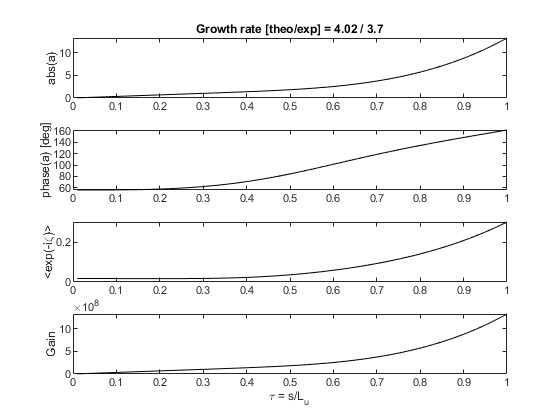

subplot(4,1,2); plot(tau,data(:,2),'k'); ylabel('phase(a) [deg]');
subplot(4,1,3); plot(tau,data(:,3),'k'); ylabel('<exp(-i\zeta)>');
subplot(4,1,4); plot(tau,data(:,4),'k'); ylabel('Gain');
xlabel('\tau = s/L_u')

## Appendix

The function pendulumtracker2_phase() integrates the equations of motion for a mathematical pendulum in terms of Jacobi elliptic functions. It is very similar to the one used in Chapter 5 (see those examples), exept this one takes the phase of the ponderomotive force $\phi$ into account.

function xout=pendulumtracker2_phase(x,omega,phi,dt)
x(1)=x(1)-pi/2+phi;   % adjust to new phase
k2=(0.5*x(2)/omega)^2+sin(0.5*x(1))^2; k=sqrt(k2);
if (x(1)>pi) x(1)=x(1)-2*pi; end
if (x(1)<-pi) x(1)=x(1)+2*pi; end
s=1; if (x(1)<0) s=-s; x(1)=-x(1); end
s1=1; if (x(2)<0) s1=-s1; end
if (k>1)   % outside separatrix; check this part next
  kelf=ellipke(1/k2);
  trev=2*kelf/(k*omega);
  t0=mod(dt,trev);
  tmp=s1*k*omega*t0+s*elliptic12(0.5*x(1),1/k2);
  [sn,cn,dn]=ellipj(tmp,1/k2);    
  if (abs(tmp) > kelf) sn=-sn; end
  xout(1)=2*asin(sn);
  xout(2)=2*s1*omega*k*dn;
else       % inside separatrix
  trev=4*ellipke(k2)/omega;
  t0=mod(dt,trev);
  z0=asin(min(1,sin(0.5*x(1))/k));
  tmp=s1*omega*t0+s*elliptic12(z0,k2);
  [sn,cn,dn]=ellipj(tmp,k2);  
  xout(1)=2*asin(k*sn);
  xout(2)=2*s1*omega*k*cn;
end
x(1)=x(1)+pi/2-phi;    % adjust phase back
xout(1)=xout(1)+pi/2-phi;
if (xout(1)>3*pi/2) xout(1)=xout(1)-2*pi; end  
if (xout(1)<-pi/2) xout(1)=xout(1)+2*pi; end
end